# Introduction

The [gkaModelEye](https://github.com/gkaguirrelab/gkaModelEye) allows you to examine the appearance and optical properties of a software model of the human eye. 

The model is described in these publications:

- GK Aguirre (2019) [A Model of the Entrance Pupil of the Human Eye](https://www.nature.com/articles/s41598-019-45827-3). Scientific Reports, volume 9, Article number: 9360 (2019) 

- GK Aguirre (2021) [A Model of the Appearance of the Moving Human Eye](https://www.biorxiv.org/content/10.1101/2021.02.02.429411v1). bioRxiv 

## Setup

If you have [toolboxToolbox tBtB](https://github.com/ToolboxHub/ToolboxToolbox) installed, issue the command `tbUse('gkaModelEye');` in the console. Alternatively, you can simply add the repository (and its subdirectories) to the Matlab path using `addpath(genpath('myLocalPath/gkaModelEye'));`

This repository requires several of the MATLAB toolboxes. You can test for the availability of the necessary MATLAB toolboxes by running the script `gkaModelEyeLocalHookTemplate.m` that is located within the `config` directory.

An improvement in execution time of the code can be achieved by compiling the ray tracing routines. To do so, issue the command `compileInverseRayTrace` at the MATLAB console. The MEX files will be compiled and placed in the `bin` directory of this repository.

## Creating and displaying an eye

You can define a model eye with this call:

eye = modelEyeParameters();

The function `modelEyeParameters` accepts a number of key-value pairs that adjust the properties of the model, such as the refractive error and accommodative state of the eye. The returned variable `modelEye` is a structure:

eye

eye = struct with fields:
               meta: [1×1 struct]
      derivedParams: [1×1 struct]
              index: [1×1 struct]
             cornea: [1×1 struct]
               iris: [1×1 struct]
               stop: [1×1 struct]
             retina: [1×1 struct]
               lens: [1×1 struct]
    rotationCenters: [1×1 struct]
          landmarks: [1×1 struct]

The various fields of the structure the anatomical properties of the model. The eye is modeled as a set of *quadric surfaces*. These are 3D surfaces such as spheres, ellipsoids, hyperboloids, and parabaloids. These surfaces can refract light (following Snell's law) and the software implements ray-tracing to measure various properties of the eye.

There are various displays and renders that can be created from the model. Here is a schematic of the eye in the horizontal plane:

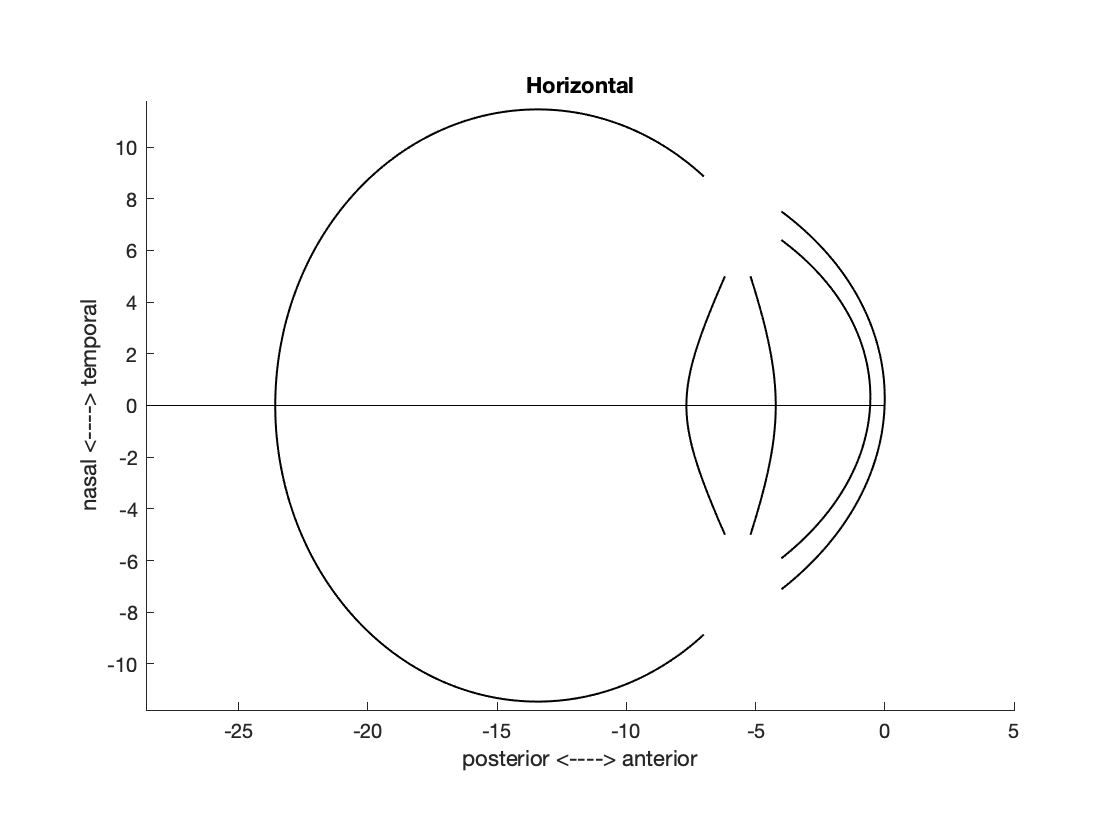

plotModelEyeSchematic(eye);

From the right to the left of the figure we see the front and back surface of the cornea, the front and back surface of the lens, and then the interior surface of the retina of the eye. The line that travels through the middle of the eye is the *optical axis*, and the elements of the eye are (mostly) centered on this line.

## Measuring optical properties and modifying the model

With the eye now defined, you can measure various things. 

This is a measurement of the optical power of the eye, expressed in diopters:

opticalPower = calcOpticalPower(eye)

opticalPower = 64.7640

You can modify the model and examine the effect on the output. We specify accommodation in units of diopters. For example, the default model eye has a "resting" accommodation of 1.5 D, meaning that it is focused on points that are `1000 mm / 1.5 D = 667 mm` distant. We could create a model in which the eye is focused on a closer point. This accommodative change should be reflected in the optical power of the eye. Accommodation at 10D indicates that the eye is best focused for objects that are 100 mm distant from the first principal point of the eye.

focusedEye = modelEyeParameters('accommodation',10);
opticalPower = calcOpticalPower(focusedEye)

opticalPower = 74.4837

If we draw an updated schematic of the eye (red), we will see that the lens has become thicker and changed shape, which is what has allowed the eye to focus upon a closer point.

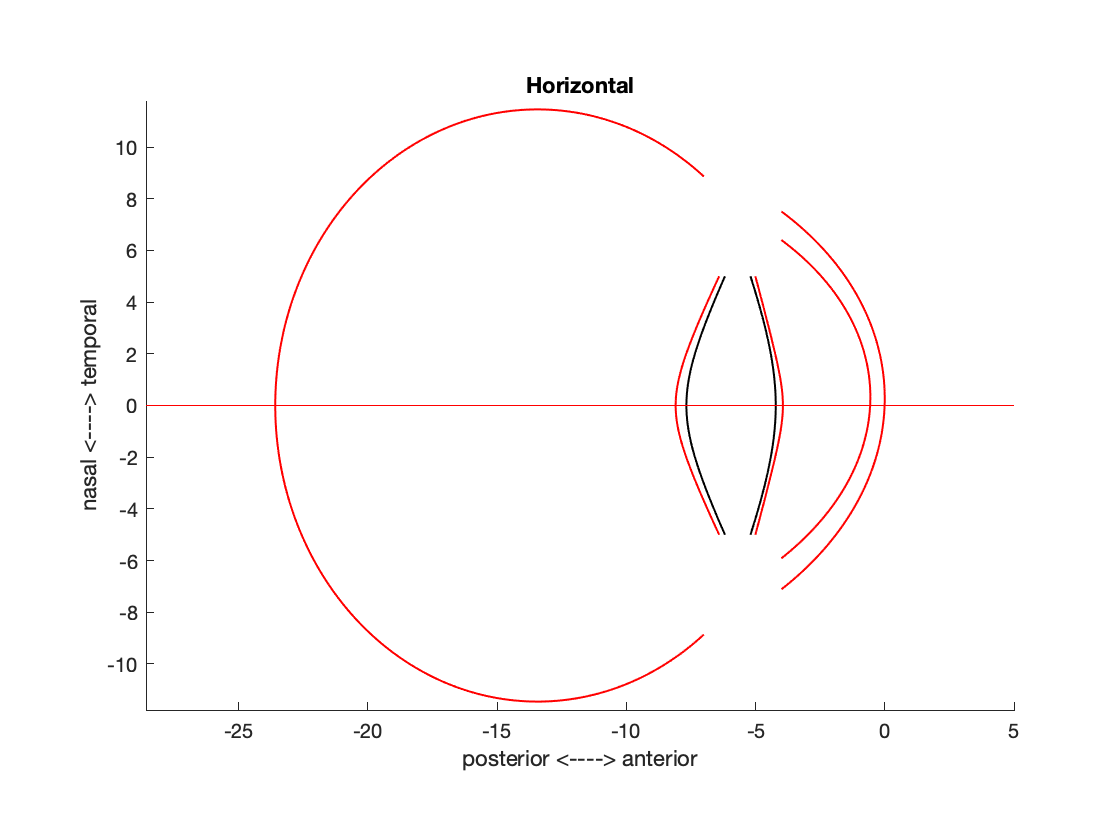

plotModelEyeSchematic(eye);
plotModelEyeSchematic(focusedEye,'newFigure',false,'plotColor','r');

## Creating a sceneGeometry

Sometimes we would like to examine the how our model eye would look as seen from a camera. The relationship between the model eye, the camera, and other items in the world is defined by the *sceneGeometry*:

sceneGeometry = createSceneGeometry();

This variable is also a structure, and one of those structures is itself a model eye:

sceneGeometry

sceneGeometry = struct with fields:
    cameraIntrinsic: [1×1 struct]
     cameraPosition: [1×1 struct]
     screenPosition: [1×1 struct]
                eye: [1×1 struct]
         refraction: [1×1 struct]
               meta: [1×1 struct]

The other fields define properties of the camera and other elements required for ray tracing.

We can use the sceneGeometry to explore the appearance of the eye as seen from a camera. To do so, we must specify the *pose* of the eye, which is a description of how the current rotation and size of the pupil. We define an eyePose as follows:

eyePose = [-15, 20, 0 2];

These values specify an eye that is rotated away from the camera 15° horizontally towards subject-right, 20° vertically up, and with zero degrees of torsion. The last value specifies that the radius of the pupil is 2mm (technically, this is the radius of the physical aperture stop).

With the sceneGeometry and eyePose defined, we can render the appearance of some of the features of the eye:

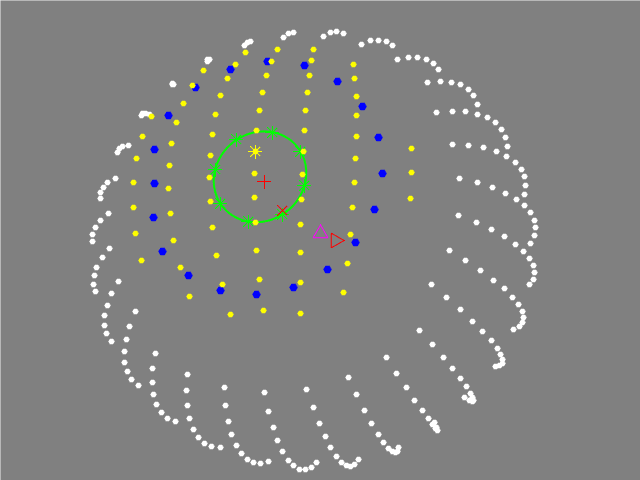

renderEyePose(eyePose,sceneGeometry);

In this image we can see several features of the eye. The surface of the retina (equivalently, the surface of the vitreous chamber) is shown in white. The front-surface of the cornea is in yellow, and the visible border of the iris is in blue. The green asterixes, and green ellipse, define the border of the entrance pupil of the eye.